qi = [0 0 0]

qi =      0     0     0


qf = rand(1,3)

qf =     0.6948    0.3171    0.9502


qf = qf/norm(qf)

qf =     0.5699    0.2601    0.7794


t = 10

t = 10


% syms s k alpha_x alpha_y beta_x beta_y
% x = s^3 * qf(1) - (s-1)^3*qi(1) + alpha_x*s^2*(s-1) + beta_x*s*(s-1)^2
% y = s^3 * qf(2) - (s-1)^3*qi(2) + alpha_y*s^2*(s-1) + beta_y*s*(s-1)^2
% k=2
% alpha_x= k *cos(qf(3)) - 3*qf(1)
% alpha_y= k *sin(qf(3)) - 3*qf(2)
% beta_x= k *cos(qi(3)) + 3*qi(1)
% beta_y= k *sin(qi(3)) - 3*qi(1)
% 
% x = s^3 * qf(1) - (s-1)^3*qi(1) + alpha_x*s^2*(s-1) + beta_x*s*(s-1)^2
% y = s^3 * qf(2) - (s-1)^3*qi(2) + alpha_y*s^2*(s-1) + beta_y*s*(s-1)^2
% 
% x_dot = jacobian(x, s)
% y_dot = jacobian(y, s)
[s,s_dot,s_dotdot] = trap_profile(0, 5, 20, qi, qf);

% s=0:0.001:1
k=1

k = 1

alpha_x= k *cos(qf(3)) - 3*qf(1)

alpha_x = -0.9985

alpha_y= k *sin(qf(3)) - 3*qf(2)

alpha_y = -0.0774

beta_x= k *cos(qi(3)) + 3*qi(1)

beta_x = 1

beta_y= k *sin(qi(3)) - 3*qi(1)

beta_y = 0


x = s.^3.*qf(1) - (s-1).^3.*qi(1) + alpha_x.*s.^2.*(s-1) + beta_x.*s.*(s-1).^2

x =          0    0.0002    0.0009    0.0021    0.0037    0.0057    0.0082    0.0111    0.0145    0.0183    0.0224    0.0270    0.0320    0.0373    0.0430    0.0491    0.0554    0.0621    0.0691    0.0763    0.0838    0.0916    0.0995    0.1077    0.1160    0.1246    0.1332    0.1420    0.1509    0.1598    0.1689    0.1780    0.1872    0.1963    0.2054    0.2142    0.2228    0.2311    0.2392    0.2472    0.2549    0.2624    0.2698    0.2770    0.2841    0.2911    0.2979    0.3046    0.3113    0.3178


y = s.^3.*qf(2) - (s-1).^3.*qi(2) + alpha_y.*s.^2.*(s-1) + beta_y.*s.*(s-1).^2

y =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0018    0.0021    0.0025    0.0030    0.0036    0.0042    0.0049    0.0057    0.0067    0.0077    0.0088    0.0101    0.0115    0.0129    0.0145    0.0162    0.0181    0.0200    0.0221    0.0243    0.0267    0.0291    0.0318    0.0346    0.0375    0.0406




x_dot = 3.*s.^2.*qf(1) - 3.*(s-1).^2.*qi(1) + alpha_x.*s.*(3.*s-2) + beta_x.*(3.*s-1).*(s-1)

x_dot =     1.0000    0.9995    0.9982    0.9959    0.9927    0.9886    0.9836    0.9777    0.9709    0.9633    0.9549    0.9457    0.9357    0.9249    0.9133    0.9011    0.8882    0.8747    0.8605    0.8458    0.8305    0.8148    0.7986    0.7820    0.7651    0.7479    0.7304    0.7128    0.6950    0.6772    0.6593    0.6415    0.6239    0.6064    0.5894    0.5733    0.5579    0.5433    0.5294    0.5164    0.5042    0.4927    0.4820    0.4721    0.4630    0.4547    0.4472    0.4405    0.4345    0.4294


y_dot = 3.*s.^2.*qf(2) - 3.*(s-1).^2.*qi(2) + alpha_y.*s.*(3.*s-2) + beta_y.*(3.*s-1).*(s-1)

y_dot =          0    0.0000    0.0001    0.0003    0.0006    0.0009    0.0013    0.0018    0.0024    0.0031    0.0038    0.0047    0.0057    0.0068    0.0081    0.0095    0.0110    0.0127    0.0146    0.0166    0.0188    0.0213    0.0240    0.0269    0.0301    0.0335    0.0372    0.0413    0.0456    0.0503    0.0554    0.0608    0.0667    0.0730    0.0796    0.0865    0.0936    0.1010    0.1086    0.1165    0.1246    0.1330    0.1416    0.1505    0.1597    0.1691    0.1787    0.1886    0.1987    0.2091



x_ddot = 6.*s.*qf(1) - 6.*(s-1).*qi(1) + alpha_x.*(6.*s-2) + beta_x.*(6.*s-4)

x_ddot =    -2.0030   -2.0022   -1.9998   -1.9959   -1.9904   -1.9833   -1.9746   -1.9644   -1.9526   -1.9392   -1.9243   -1.9077   -1.8896   -1.8700   -1.8487   -1.8259   -1.8015   -1.7755   -1.7480   -1.7188   -1.6881   -1.6559   -1.6220   -1.5866   -1.5496   -1.5110   -1.4709   -1.4292   -1.3859   -1.3410   -1.2946   -1.2466   -1.1970   -1.1458   -1.0939   -1.0419   -0.9900   -0.9380   -0.8861   -0.8341   -0.7822   -0.7302   -0.6783   -0.6264   -0.5744   -0.5225   -0.4705   -0.4186   -0.3666   -0.3147


y_ddot = 6.*s.*qf(2) - 6.*(s-1).*qi(2) + alpha_y.*(6.*s-2) + beta_y.*(6.*s-4)

y_ddot =     0.1549    0.1551    0.1559    0.1571    0.1589    0.1612    0.1639    0.1672    0.1710    0.1753    0.1800    0.1853    0.1911    0.1974    0.2042    0.2115    0.2193    0.2276    0.2364    0.2457    0.2555    0.2658    0.2767    0.2880    0.2998    0.3121    0.3250    0.3383    0.3521    0.3665    0.3813    0.3967    0.4125    0.4289    0.4455    0.4621    0.4787    0.4953    0.5119    0.5285    0.5451    0.5617    0.5783    0.5949    0.6115    0.6281    0.6448    0.6614    0.6780    0.6946



theta=atan2(y_dot,x_dot)

theta =          0    0.0000    0.0001    0.0003    0.0006    0.0009    0.0013    0.0019    0.0025    0.0032    0.0040    0.0050    0.0061    0.0074    0.0088    0.0105    0.0124    0.0145    0.0169    0.0196    0.0227    0.0261    0.0300    0.0344    0.0393    0.0448    0.0509    0.0578    0.0656    0.0742    0.0838    0.0946    0.1065    0.1198    0.1342    0.1497    0.1662    0.1838    0.2023    0.2219    0.2423    0.2637    0.2858    0.3086    0.3321    0.3559    0.3802    0.4046    0.4290    0.4533


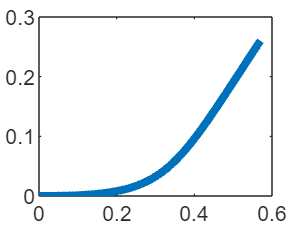


plot(x,y,'LineWidth',3)

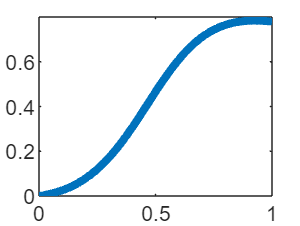

plot(s,theta,'LineWidth',3)

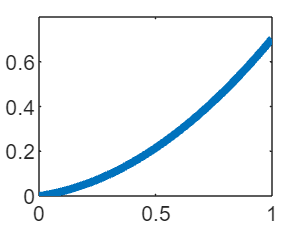

plot(s,y_dot,'LineWidth',3)

max(x_dot)

ans = 1

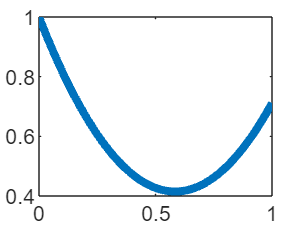

plot(s,x_dot,'LineWidth',3)


v = sqrt(x_dot.^2 + y_dot.^2) .* s_dot

v =          0    0.0091    0.0181    0.0272    0.0361    0.0449    0.0536    0.0622    0.0706    0.0788    0.0868    0.0946    0.1021    0.1093    0.1162    0.1229    0.1292    0.1352    0.1408    0.1461    0.1510    0.1556    0.1598    0.1636    0.1671    0.1701    0.1729    0.1753    0.1773    0.1790    0.1805    0.1816    0.1825    0.1832    0.1784    0.1739    0.1697    0.1658    0.1621    0.1588    0.1558    0.1531    0.1507    0.1487    0.1469    0.1455    0.1445    0.1437    0.1433    0.1433


w = (y_ddot.*x_dot - x_ddot.*y_dot)./(x_dot.^2 + y_dot.^2) .* s_dot

w =          0    0.0014    0.0028    0.0043    0.0059    0.0075    0.0092    0.0111    0.0132    0.0154    0.0179    0.0206    0.0236    0.0270    0.0307    0.0349    0.0396    0.0448    0.0506    0.0570    0.0643    0.0724    0.0814    0.0915    0.1027    0.1152    0.1291    0.1445    0.1616    0.1805    0.2013    0.2242    0.2492    0.2764    0.2965    0.3169    0.3373    0.3575    0.3772    0.3962    0.4141    0.4307    0.4455    0.4583    0.4688    0.4767    0.4817    0.4838    0.4828    0.4788


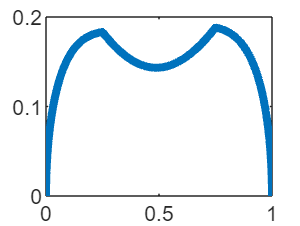

plot(s,v,'LineWidth',3)

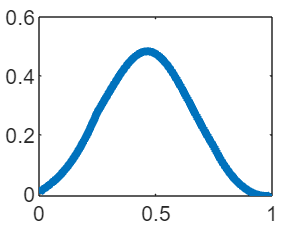

plot(s,w,'LineWidth',3)

max(v)

ans = 0.1882

max(w)

ans = 0.4838

b = 1

b = 1

k1 = 20

k1 = 20

k2 = 20

k2 = 20

y1_des = x + b.*cos(theta)

y1_des =     1.0000    1.0002    1.0009    1.0021    1.0037    1.0057    1.0082    1.0111    1.0145    1.0182    1.0224    1.0270    1.0320    1.0373    1.0430    1.0490    1.0553    1.0620    1.0689    1.0761    1.0836    1.0912    1.0991    1.1071    1.1153    1.1235    1.1319    1.1403    1.1487    1.1571    1.1654    1.1735    1.1815    1.1892    1.1964    1.2030    1.2090    1.2143    1.2188    1.2226    1.2257    1.2279    1.2293    1.2298    1.2295    1.2284    1.2265    1.2239    1.2207    1.2168


y2_des = y + b.*sin(theta)

y2_des =          0    0.0000    0.0001    0.0003    0.0006    0.0009    0.0013    0.0019    0.0025    0.0032    0.0041    0.0051    0.0062    0.0075    0.0090    0.0107    0.0127    0.0149    0.0174    0.0203    0.0235    0.0271    0.0312    0.0358    0.0410    0.0469    0.0535    0.0608    0.0691    0.0783    0.0886    0.1001    0.1129    0.1272    0.1427    0.1593    0.1769    0.1957    0.2155    0.2363    0.2580    0.2806    0.3040    0.3281    0.3526    0.3776    0.4029    0.4282    0.4534    0.4785


y1_dot_des = cos(theta).*v - b.*sin(theta).*w

y1_dot_des =          0    0.0091    0.0181    0.0272    0.0361    0.0449    0.0536    0.0622    0.0706    0.0788    0.0867    0.0945    0.1019    0.1091    0.1160    0.1225    0.1287    0.1345    0.1400    0.1450    0.1495    0.1537    0.1573    0.1604    0.1629    0.1648    0.1661    0.1666    0.1663    0.1652    0.1630    0.1596    0.1550    0.1489    0.1372    0.1247    0.1116    0.0977    0.0830    0.0677    0.0519    0.0356    0.0190    0.0024   -0.0139   -0.0297   -0.0446   -0.0583   -0.0705   -0.0809


y2_dot_des = sin(theta).*v + b.*cos(theta).*w

y2_dot_des =          0    0.0014    0.0028    0.0043    0.0059    0.0075    0.0093    0.0112    0.0133    0.0157    0.0182    0.0211    0.0243    0.0278    0.0318    0.0362    0.0412    0.0467    0.0529    0.0599    0.0677    0.0764    0.0862    0.0970    0.1092    0.1227    0.1377    0.1544    0.1729    0.1932    0.2157    0.2403    0.2672    0.2963    0.3177    0.3393    0.3607    0.3817    0.4021    0.4214    0.4394    0.4557    0.4699    0.4818    0.4911    0.4975    0.5009    0.5013    0.4987    0.4932



x_des = timeseries(x)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

y_des = timeseries(y)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

y1_des = timeseries(y1_des)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

y2_des =  timeseries(y2_des)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

y1_dot_des = timeseries(y1_dot_des)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

y2_dot_des = timeseries(y2_dot_des)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 